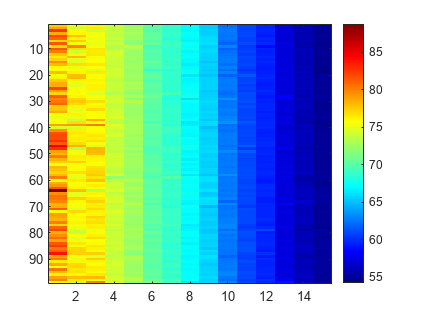

% Connect to sensor and run this

% Uncomment following 3 lines for sensor input
% ElikoReconnect();
% output = ElikoSample();
% PicometerControl('Disconnect');

% real1 = real(output(:,1));
% imag1 = imag(output(:,1));
% 
% plot(real1,imag1,'g*');

% Compute the magnitudes of each number in the matrix
magnitude_matrix = abs(output);

% Plot the magnitude matrix as image or heatmap
imagesc(magnitude_matrix);
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

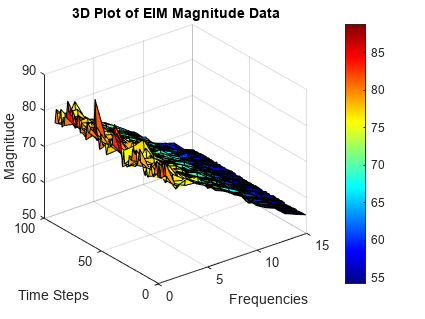


% Assuming magnitude_matrix contains your magnitude data
figure;
surf(magnitude_matrix);

% Customize the plot appearance
title('3D Plot of EIM Magnitude Data');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference


% Set percentage threshold to identify noise (above threshold is noise)
percentage_threshold = 90;

% Initialize arrays to store thresholds and signal masks for each frequency
num_frequencies = size(magnitude_matrix, 2)  % Assuming magnitude_matrix is Mx15

num_frequencies = 15

thresholds = zeros(1, num_frequencies)

thresholds =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Initialize arrays to store frequency analysis results for signal and noise
signal_fft_results = cell(1, num_frequencies);
noise_fft_results = cell(1, num_frequencies);

for i = 1:num_frequencies
    % Calculate the maximum magnitude for the current frequency
    max_magnitude = max(magnitude_matrix(:, i));

    % Calculate the threshold value as a percentage of the maximum magnitude
    threshold = (percentage_threshold / 100) * max_magnitude;

    % Create a binary mask where 1 represents signal and 0 represents noise
    signal_mask = magnitude_matrix(:, i) >= threshold;

    % Store the threshold and signal mask for the current frequency
    thresholds(i) = threshold;
end

thresholds

thresholds =    79.9237   71.8938   72.2518   67.3890   66.2498   64.0685   63.0715   61.0732   59.5743   57.1321   55.4622   54.6634   53.0424   51.4073   49.8959


% Apply the masks to the magnitude matrix for each frequency
signal_data = zeros(99,15);
noise_data = zeros(99,15);

for i=1:num_frequencies
    noise_data(:,i) = magnitude_matrix(:,i)-thresholds(i);
    signal_data(:,i) = magnitude_matrix(:,i)-noise_data(:,i);
end 
% signal_data = magnitude_matrix .* cat(2, signal_masks{:});  % Signal components
% noise_data = magnitude_matrix - signal_data;  % Noise components

signal_fft_results = fft(signal_data)

signal_fft_results = 1.0e+03 *

   7.9125 + 0.0000i   7.1175 + 0.0000i   7.1529 + 0.0000i   6.6715 + 0.0000i   6.5587 + 0.0000i   6.3428 + 0.0000i   6.2441 + 0.0000i   6.0462 + 0.0000i   5.8979 + 0.0000i   5.6561 + 0.0000i   5.4908 + 0.0000i   5.4117 + 0.0000i   5.2512 + 0.0000i   5.0893 + 0.0000i   4.9397 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0

noise_fft_results = fft(noise_data)

noise_fft_results = 1.0e+02 *

  -0.8329 + 0.0000i   4.1156 + 0.0000i   3.9379 + 0.0000i   6.4825 + 0.0000i   6.2252 + 0.0000i   6.0636 + 0.0000i   5.7472 + 0.0000i   5.9226 + 0.0000i   5.9645 + 0.0000i   5.3555 + 0.0000i   5.2979 + 0.0000i   4.9028 + 0.0000i   4.2553 + 0.0000i   4.5944 + 0.0000i   5.0173 + 0.0000i
  -0.0909 + 0.3673i   0.0377 - 0.0917i  -0.1320 + 0.0870i  -0.0013 + 0.0216i  -0.0095 + 0.0074i   0.0371 + 0.0375i   0.0098 + 0.0394i   0.0053 + 0.0117i  -0.0050 + 0.0066i  -0.0456 + 0.0166i  -0.0361 + 0.0171i  -0.0145 + 0.0306i   0.0282 + 0.0240i  -0.0087 + 0.0330i   0.0069 + 0.0569i
   0.0759 + 0.1260i   0.0925 - 0.0064i   0.0844 + 0.0859i  -0.0230 + 0.0354i   0.0031 + 0.0032i   0.0038 + 0.0238i   0.0343 - 0.0153i   0.0095 - 0.0350i   0.0373 + 0.0010i  -0.0089 + 0.0247i   0.0060 + 0.0343i  -0.0009 + 0.0266i  -0.0033 + 0.0059i  -0.0024 + 0.0073i  -0.0013 + 0.0240i
  -0.0707 - 0.1574i   0.0139 + 0.0284i  -0.0008 - 0.0048i   0.0350 - 0.0207i   0.0215 - 0.0028i   0.0448 + 0.03

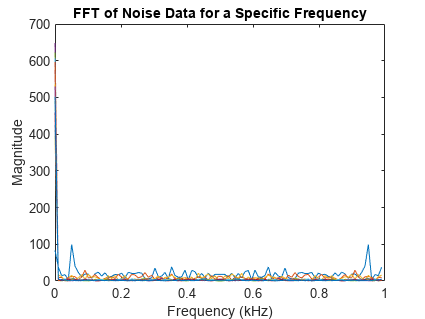

% Calculate the number of data points and the sampling frequency (Fs)
num_points = length(noise_fft_results);
Fs = 1;  % Replace with your actual sampling frequency

% Generate the frequency axis
frequencies = (0:num_points-1) * (Fs / num_points);

% Plot the FFT result
figure;
plot(frequencies, abs(noise_fft_results));
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('FFT of Noise Data for a Specific Frequency');

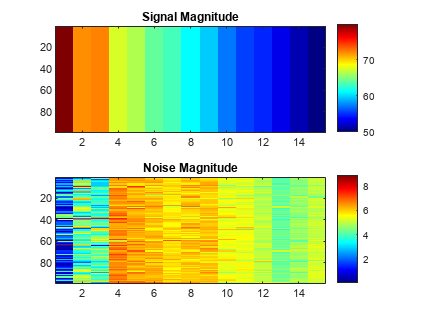

% % Calculate the maximum magnitude value in your data
% max_magnitude = max(magnitude_matrix(:));
% 
% % Calculate threshold
% threshold = (percentage_threshold / 100) * max_magnitude;
% 
% signal_mask = magnitude_matrix >= threshold;
% 
% signal_data = magnitude_matrix .* signal_mask;  % Apply the mask to your complex data
% noise_data = magnitude_matrix .* ~signal_mask;   % Apply the inverse mask for noise

% Visualize the signal and noise separately
figure;
subplot(2, 1, 1);
imagesc(abs(signal_data));
title('Signal Magnitude');
colormap('jet');
colorbar;
subplot(2, 1, 2);
imagesc(abs(noise_data));
title('Noise Magnitude');
colormap('jet');
colorbar;

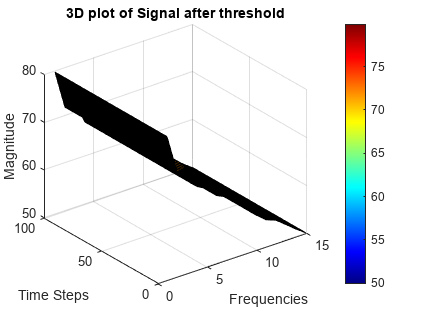



% 3D plot of Signal after threshold
figure;
surf(signal_data);

% Customize the plot appearance
title('3D plot of Signal after threshold');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

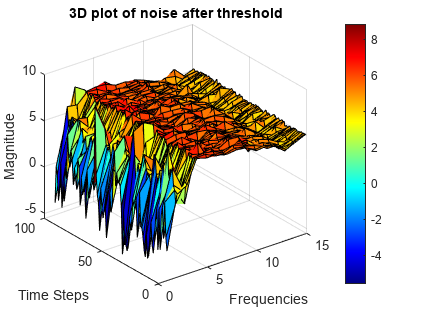


% 3D plot of noise after threshold
figure;
surf(noise_data);

% Customize the plot appearance
title('3D plot of noise after threshold');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

% Designing and applying a bandpass filter
fpass = [0 0.2];  % Passband frequency range in Hz

bpFilt = designfilt('bandpassiir','FilterOrder',10, ...
         'HalfPowerFrequency1',500,'HalfPowerFrequency2',560, ...
         'SampleRate',1500);

% Apply the filter to your data
% filtered_data = bandpass(output, fpass, Fs);

% Repeat the same process for the higher frequency range (251 to 349 kHz)

% fpass = [251000, 349000];  % Passband frequency range in Hz
% order = 10;  % Filter order (adjust as needed)
% bp_filter = designfilt('bandpassiir', 'FilterOrder', order, 'PassbandFrequency', fpass, 'SampleRate', Fs);
% 
% % Apply the filter to your data
% filtered_data = filtfilt(bp_filter, your_data);

% fvtool(bpFilt)

dataOut = filter(bpFilt,output);
filter_result_mat = abs(dataOut);

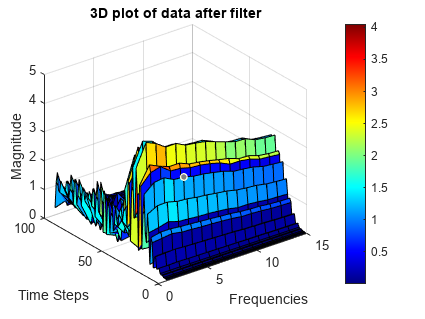

% 3D plot of noise after threshold
figure;
surf(filter_result_mat);

% Customize the plot appearance
title('3D plot of data after filter');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference